# Mảng

[Menu menu chính](matlab:open('MainMenu.mlx'))

Cả hai doubles và chuỗi đều *vô hướng *vì chúng đại diện cho các giá trị đơn. Nhiều chương trình yêu cầu nhiều hơn một giá trị để làm việc. Các lập trình viên dẫn này đến khái niệm một mảng như một tập hợp các giá trị được lập chỉ mục. Một vectơ dữ liệu có thể theo dõi một cái gì đó giống như nhiệt độ tại trạm thời tiết trong suốt thời gian. Một ma trận có thể bao gồm các cột cho từng giá trị theo dõi của nhiệt độ, độ ẩm, lượng mưa và áp suất khí áp mỗi lần. Nếu bạn muốn theo dõi một số giá trị theo thời gian tại nhiều trạm thời tiết, thì bạn sẽ yêu cầu một mảng 3 chiều được lập chỉ mục theo thời gian, biến thời tiết và định danh trạm thời tiết.

[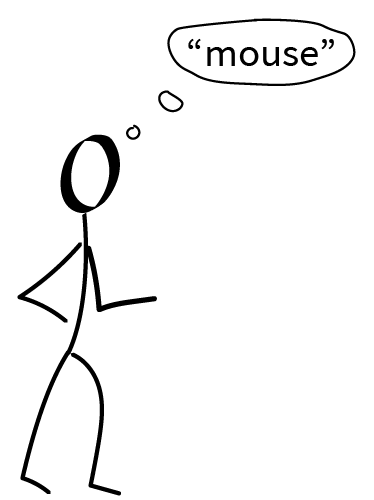](matlab:open('./Arrays.mlx'))   [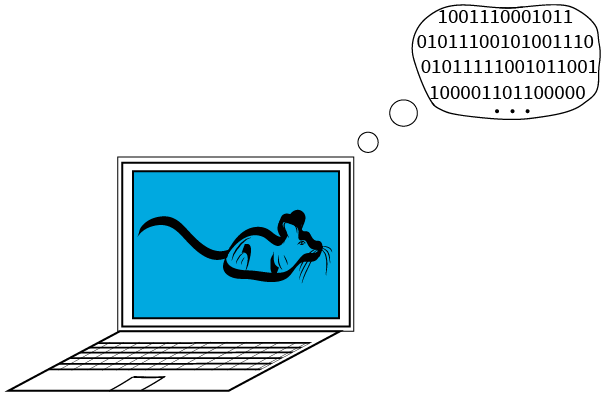](matlab:open('./Arrays.mlx'))

Kịch bản này sẽ giới thiệu các vectơ, ma trận và mảng 3 chiều.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN  **View** tab của công cụ MATLAB, trong **View** section, chọn **Output Inline**. Thay phiên, chọn **Output inline **Sử dụng biểu tượng   Ở phía trên bên phải của Live Editor pane.

 Tương tác với tập lệnh trực tiếp này sẽ xây dựng một số quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau, nhưng một số quen thuộc với môi trường biên tập trực tiếp đã được giới thiệu trong [Giới thiệu.MLX](matlab:open('./Introduction.mlx'))

  Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm cả chạy tất cả các khối mã.

## Cấu trúc dữ liệu hỗn hợp

### Vectơ

MỘT *Vector *của các giá trị là một danh sách các phần tử được lập chỉ mục một chiều có thể được sắp xếp theo chiều ngang (một vectơ hàng), chẳng hạn như ví dụ

% run this code
DaysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

hoặc theo chiều dọc (một vectơ cột), chẳng hạn như ví dụ

Ordinals = ["first";"second";"third";"fourth";"fifth"]

Lưu ý rằng mỗi vectơ được dán nhãn với một cặp số. Vectơ hàng được gọi là  `1x7 string `Bởi vì nó có 1 hàng và 7 cột, mỗi cột chứa một [phần tử chuỗi](matlab:open('./Data.mlx')). Vectơ cột được gọi là  `5x1 string `Vì nó chứa 5 hàng và 1 cột, mỗi hàng chứa một phần tử chuỗi. Nói chung, mỗi phần tử trong một vectơ phải là cùng loại dữ liệu. Chúng ta có thể tạo một vectơ cột chứa  [doubles](matlab:open('./Data.mlx'))

Num = [6; 7]

và thậm chí các vectơ kết hợp với nhau dọc theo một chiều phù hợp:

NewVector = [Ordinals;Nums]

Nhưng nếu ngôn ngữ lập trình cho phép điều này xảy ra, nó sẽ thực thi một loại chung cho mọi yếu tố của kết quả. Trong ví dụ về `NewVector `điều đó có nghĩa là các yếu tố đã được nhân đôi trong `nums `Trở thành chuỗi trong `NewVector`

#### Lập chỉ mục

Nhớ lại rằng một vector được xác định là một chiều *lập chỉ mục *Danh sách các phần tử. Điều này có nghĩa là, với tư cách là một lập trình viên, bạn có thể truy cập một phần tử (hoặc phạm vi của các phần tử) trong một vectơ bằng cách xác định chúng theo chỉ mục (nghĩa là theo số) trong danh sách.

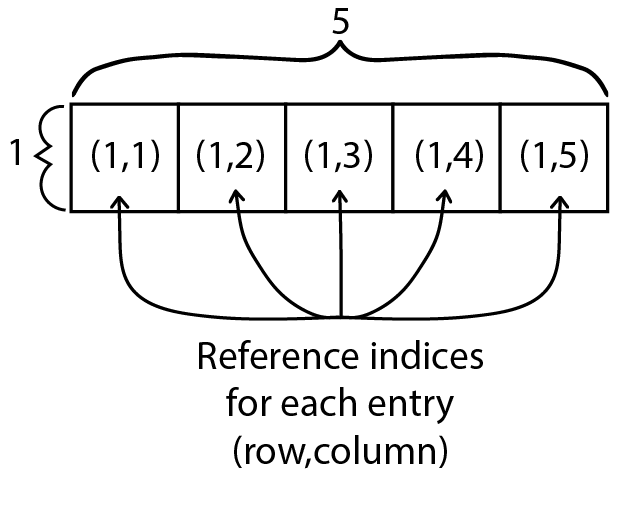

Các ngôn ngữ lập trình khác nhau trong việc lập chỉ mục của chúng, nhưng chúng bắt đầu lập chỉ mục các phần tử với 1 (như MATLAB) hoặc 0 (chẳng hạn như Python). Vì chỉ có một chỉ mục thay đổi trong một vectơ (chỉ số cột cho các vectơ hàng hoặc chỉ mục hàng cho các vectơ cột), chỉ số đơn là đủ để xác định duy nhất mục nhập.

% run this code
DaysOfWeek(5)
Ordinals(2:4)
k = 3;
"The " + Ordinals(k) + " day of the week is " + DaysOfWeek(k) + "."

  **Thử**

- Chạy mã bên dưới.

- Sau đó chạy mã mà không cần chuyển vị `DaysOfWeek`. Có gì khác nhau?

- Hàm `transpose()` làm chức năng gì? Làm thế nào bạn có thể tìm ra nó?

- Điều gì xảy ra nếu bạn chạy lệnh để đặt giá trị của `allDays `với `NewVector `Thay vì `Ordinals`? Hoặc với `DaysOfWeek `Thay vì `DaysOfWeek(1:5)`? Hoặc cả hai?

AllDays = "The " + Ordinals + " day of the week is " + transpose(DaysOfWeek(1:5)) + "."

  **Pro-tip**. Một cách khác để tìm sự chuyển vị của một ma trận `M `Trong Matlab là viết `M'`

#### Cộng vector

Bổ sung vector yêu cầu các vectơ trong câu hỏi có cùng kích thước. Nếu các kích thước giống hệt nhau, hoạt động sẽ tiến hành thời hạn với mỗi phần tử được thêm vào phần tử có cùng chỉ số trong ma trận khác.

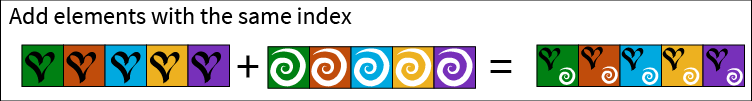

Như trong trường hợp kết hợp của `string` types và `double` types  dẫn đến đầu ra là các giá trị `string`, MATLAB được thiết kế để thay đổi cấu trúc dữ liệu của bạn nếu cần phải thực thi lệnh. Trong trường hợp của

AllDays = "The " + Ordinals + " day of the week is " + transpose(DaysOfWeek(1:5)) + "."

nó là cần thiết để mở rộng vectơ `1x1 "The" `Và  `" day of the week is "` and "." thành vectơ `5x1`, giống như `Ordinals `Và `DaysOfWeek(1: 5) `Như đã hiển thị:

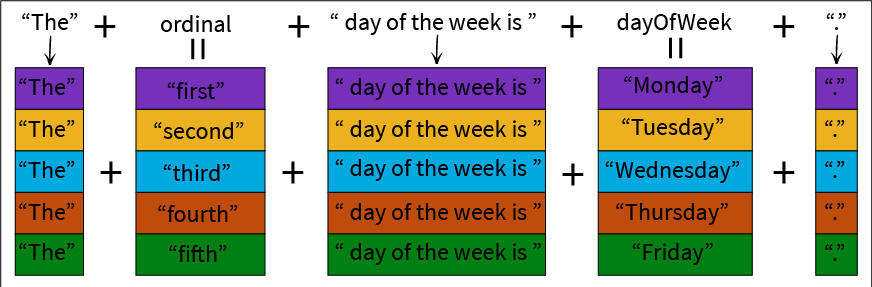

Kết nối từng phần tử với các giá trị chỉ mục tương ứng (trong trường hợp này là màu khớp) trong các vectơ khác, kết quả là một Vector `5x1 ` của chuỗi.

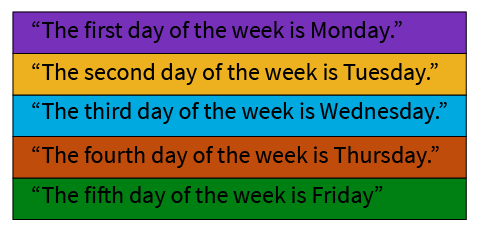

 **Phản ánh**

- Hoạt động của Vector có thể cực kỳ hiệu quả, nhưng bạn cũng có thể vô tình thực hiện một hoạt động rất khác so với dự định. Làm thế nào bạn có thể kiểm tra xem bạn có, trên thực tế, đã thực hiện hoạt động của bạn?

- Bạn nghĩ điều gì sẽ xảy ra nếu bạn thực hiện các hoạt động toán học khác liên quan đến các vectơ số? Có bất kỳ mẫu tiêu chuẩn nào cho những gì hoạt động như bạn mong đợi và những gì không?

**Ví dụ: Hoạt động toán học trên các vectơ số**

vec1 = [1 2 3 4 5]


### Ma trận

Ma trận là bộ sưu tập 2 chiều của $mn$ các yếu tố được sắp xếp trong `m `hàng và n các cột, sao cho phần tử `(i, j) `nằm trong hàng i và cột thứ j

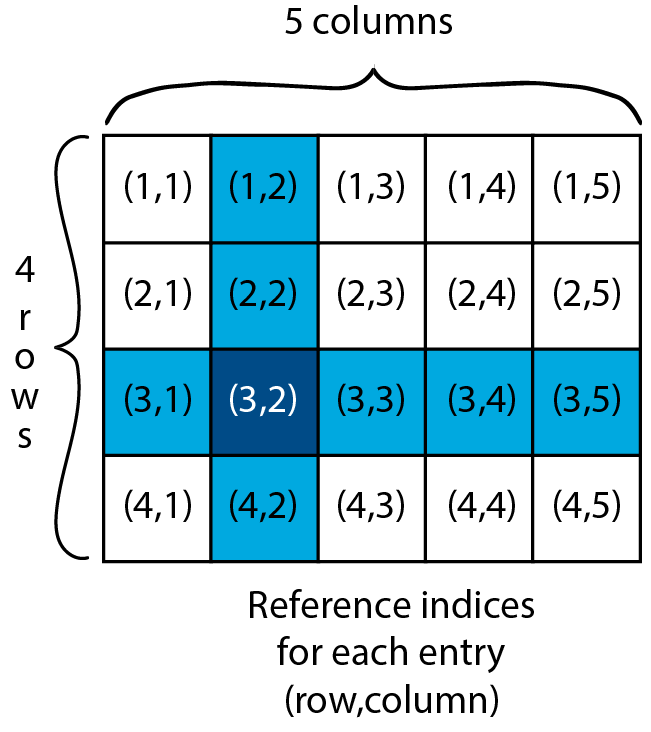

Mặc dù mọi vectơ đều tầm thường là một ma trận, kết quả của `vec7 `trong sự phản ánh Ví dụ ở trên là một Ma trận `5x5` tiêu chuẩn hơn.

#### Phép nhân ma trận

Như bạn đã thấy trong Ví dụ Ở trên, phép nhân vector đôi khi có thể dẫn đến một ma trận lớn hơn đáng kể. Điều này là do hàng `i` của ma trận đầu tiên phải được nhân lên với cột thứ `j `của ma trận thứ hai và sau đó các giá trị đó được tổng hợp để xác định giá trị `(i, j)` trong ma trận đầu ra.

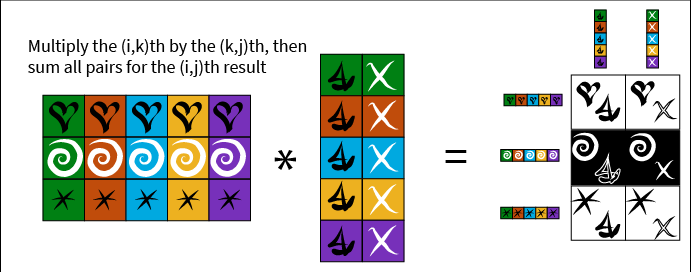

**Bài tập 1**

Sử dụng sơ đồ nhân ma trận để giải thích các kích thước và giá trị trong kết quả được tính toán

vec1 = [1 2 3 4 5];
vec7 = transpose(vec1)*vec1

**Ghi chú: **Một thuộc tính mới của phép nhân ma trận là nó không giao hoán. Trong hình trên, có một ma trận  `3x5` nhân với một ma trận `5x2 ` để dẫn đến một Ma trận `3x2`. Nếu chúng ta cố gắng tính toán một ma trận `5x2 `nhân với một Ma trận `3x5`, chúng ta thậm chí không thể bắt đầu vì hàng trên cùng (thuyền buồm, x) không chứa cùng số lượng phần tử với cột đầu tiên (tim, xoáy, sao) và do đó không thể được nhân lên.

#### Sử dụng ma trận để tổ chức thông tin

Mặc dù ma trận là các đối tượng toán học, như một cấu trúc dữ liệu mảng hai chiều mà chúng có thể được sử dụng để thu thập, tổ chức và phân tích dữ liệu gần như mọi loại.

Hãy xem xét ma trận `SimpIm0 `được đưa ra bởi

SimpleIm0 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

  **Thử**

- Bạn nghĩ Ma trận `SimpIm0 c`ó thể mã hóa thông tin gì?

- Hãy thử diễn giải ma trận dưới dạng hình ảnh. Bạn thấy gì?

% Diễn giải SimpleIm0 như một hình ảnh và mở rộng nó thành một kích thước có thể nhìn thấy
imshow (SimpleIm0, "initmagnification", 1000)

3. Điều gì sẽ xảy ra nếu chúng ta thử diễn giải ma trận `1 -Simpleim0 `như một hình ảnh?

**Thêm ví dụ:**

SimpleIm1 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0; ...
    0 0 0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...
    0 0 0 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 1 0 0 1 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 1 0 0 1 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 0 0; ...
    0 0 0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...
    0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

Bạn có thể dự đoán hình ảnh nào được mã hóa trong tệp này không? Những gì tiếp theo? Thêm mã để giải thích từng ma trận dưới dạng hình ảnh để kiểm tra ý tưởng của bạn. Bạn có thể muốn mở các số liệu kết quả bằng cách nhấp vào mũi tên ở trên cùng bên cạnh hình ảnh để bạn có thể mở rộng kích thước và nhìn kỹ hơn hoặc sử dụng Mã phóng đại được sử dụng ở trên

SimpleIm2 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0; ...
    0 0 1 1 0 0 1 0 0 0 0 0 0 1 0 0 1 1 0 0; ...
    0 0 0 1 1 0 0 1 0 0 0 0 1 0 0 1 1 0 0 0; ...
    0 0 0 1 0 1 0 0 1 0 0 1 0 0 1 0 1 0 0 0; ...
    0 0 0 1 0 0 1 0 0 1 1 0 0 1 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 1 0 1 1 0 1 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 0 1 1 1 1 0 0 0 0 1 0 0 0; ...
    0 0 0 0 1 0 0 0 0 1 1 0 0 0 0 1 0 0 0 0; ...
    0 0 0 0 1 0 0 0 0 1 1 0 0 0 0 1 0 0 0 0; ...
    0 0 0 1 0 0 0 0 1 1 1 1 0 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 1 0 1 1 0 1 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 1 0 0 1 1 0 0 1 0 0 1 0 0 0; ...
    0 0 0 1 0 1 0 0 0 0 0 0 0 0 1 0 1 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 1 1 0 0 0; ...
    0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

#### Lập chỉ mục

Giống như bạn có thể liên lạc được bởi bất kỳ ai gọi số điện thoại của bạn, mỗi phần tử của một ma trận được xác định duy nhất bởi một địa chỉ được gọi là *chỉ mục (index).*

Với các vectơ, điều này khá đơn giản vì nó có thể được tưởng tượng như một danh sách được đánh số. Trong một ma trận, một chỉ mục bao gồm hai số nguyên xác định hàng và cột của nó. Giao lộ xác định một yếu tố duy nhất.

Khả năng tham khảo theo địa chỉ này cho phép chúng tôi chọn các chương trình con hoặc thay đổi các giá trị của các phần tử trong một ma trận theo cách chọn lọc.

 % Select rows 3-12 and columns 3-18 in simpleIm
  SimpleIm1(3:12,3:18)
  imshow(SimpleIm1(3:12,3:18),"InitialMagnification",1000)

Hoặc bạn có thể thêm một đường viền đơn giản xung quanh con bướm. Ở đây, mã sử dụng một đầu từ khóa được xác định bởi chương trình khi nó đang chạy để trở thành giá trị cần thiết để đạt đến phần cuối của kích thước hiện tại. Thứ tự lập chỉ mục luôn luôn (chỉ mục hàng, chỉ mục cột).

% Display the butterfly image
Butterfly = SimpleIm2;
imshow(Butterfly,"InitialMagnification",1000)
% Flip pixels from black to white along the top edge
Butterfly(2,2:end-1) = 1;
% Flip pixels from black to white along the left edge
Butterfly(2:end-1,2) = 1;
% Flip pixels from black to white along the right edge
Butterfly(2:end-1,end-1) = 1;
% Flip pixels from black to white along the bottom edge
Butterfly(end-1,2:end-1) = 1;
% Display the resulting image after adding a border
imshow(Butterfly,"InitialMagnification",1000)

Chúng ta hãy mở rộng hình ảnh bằng 2 pixel theo mỗi hướng để tạo khoảng trống giữa bướm và biên giới. Đầu tiên thêm các vectơ cạnh ngang có kích thước `1x20 `thể hiện bằng vàng. Bây giờ ma trận là `22x20`, vì vậy chúng ta cần thêm các vectơ cạnh thẳng đứng có kích thước `22x1`, như thể hiện trong màu tím.

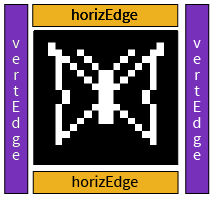

%% Pad the edges all around with black
HorizEdge = zeros([1 20]);

Invalid text character. Check for unsupported symbol, invisible character, or pasting of non-ASCII characters.

VertEdge = zeros([22 1]);
Butterfly = [VertEdge [HorizEdge;Butterfly;HorizEdge] VertEdge];
imshow(Butterfly,"InitialMagnification",1000)

Ồ không! Biên giới vẫn còn đó, bởi vì chỉ có một biến`Bươm bướm`Điều đó đang được sử dụng, và điều đó không tách biệt biên giới và con bướm vì phần đệm đã đi ra ngoài toàn bộ con số!

% Set individual pixels to separate the butterfly from the border
Butterfly(4,4) = 0;
Butterfly(4,end-3) = 0;
imshow(Butterfly,"InitialMagnification",1000)

Hoặc có thể một vài nữa:

% Finish separating the butterfly from the border
Butterfly(5,4) = 0;
Butterfly(5,end-3) = 0;
imshow(Butterfly,"InitialMagnification",1000)

Điều này đã tách con bướm khỏi biên giới, nhưng biên giới hiện là hai pixel bên trong rìa chứ không phải một.

Một vấn đề là bạn đã xác định lại ma trận`Bươm bướm`mỗi lần. Nếu bạn chỉ cần đảo ngược thứ tự của các lệnh và trước tiên mở rộng ma trận và sau đó thêm đường viền, nó sẽ trông tốt và loại bỏ một phần của con bướm sẽ không được yêu cầu để giữ cho các thành phần của hình ảnh khác biệt. Bắt đầu từ hình ảnh bướm ban đầu một lần nữa:

Butterfly = SimpleIm2;
imshow(Butterfly,"InitialMagnification",1000)

% Expand the matrix
HorizEdge = zeros([1 20]);
VertEdge = zeros([22 1]);
Butterfly = [VertEdge [HorizEdge;Butterfly;HorizEdge] VertEdge];
imshow(Butterfly,"InitialMagnification",1000)

% Add a border of white pixels one pixel inside the outer edge
Butterfly(2,2:end-1) = 1;
Butterfly(2:end-1,2) = 1;
Butterfly(2:end-1,end-1) = 1;
Butterfly(end-1,2:end-1) = 1;
imshow(Butterfly,"InitialMagnification",1000)

**Bài tập 2**

Thêm một số chi tiết vào cánh của con bướm bằng cách sử dụng lập chỉ mục để giải quyết các giá trị pixel bạn muốn thay đổi. Hãy nhớ điều đó `1 `là một pixel trắng và `0 `là một pixel màu đen.

**Bài tập 3**

Bắt đầu với ma trận

ex3 = [1 2 3; 5 6 7]

a) Thay đổi phần tử `6 thành` `13`. Điều này có nghĩa là bạn nên có `ex5 =` $\left[\matrix{ 1 & 2 & 3 \cr 5 & 13 & 7 }\right]$.

b) Trích xuất chỉ hàng đầu tiên của ma trận và gọi nó `row1ex5`. Vì vậy, bạn nên có `row1ex5 = `$\left[\matrix{1 & 2 & 3}\right]$

c) nối thêm một hàng khác để tạo ma trận `x5 = `$\left[\matrix{1 & 2 & 3 \cr 5 & 13 & 7 \cr 4 & 8 & 12}\right]$

### Tải dữ liệu bên ngoài

Trong hầu hết các trường hợp, dữ liệu mà bạn muốn phân tích sẽ đến từ bên ngoài chương trình ngay lập tức của bạn. Bạn sẽ cần nhập dữ liệu để chương trình của bạn có thể phân tích nó.

#### Các tệp liên quan đến ngôn ngữ lập trình

Bất kỳ hình ảnh đen trắng nào như con chuột này:

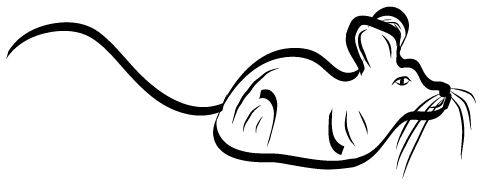

có thể được biểu diễn dưới dạng ma trận của `1` và `0`. Tuy nhiên, mặc dù việc thiết kế hình ảnh trên một lưới nhỏ của một ma trận `20x20`, con chuột này là một Ma trận `192x500`. Bạn có thể không muốn gõ cẩn thận từng giá trị đó, nhưng bạn có thể nhập một ma trận chứa chúng vào không gian làm việc của bạn.

% Import a data file that contains a black and white image of a mouse
load("Mouse.mat")
mouse
imshow(mouse)

**Thận trọng**Nếu bạn gặp lỗi ở đây, vui lòng đảm bảo rằng các nguyên tắc cơ bản của thư mục dữ liệu lập trình nằm trên đường dẫn MATLAB của bạn. Nếu bạn điều hướng hệ thống tệp của mình để hiển thị các nguyên tắc cơ bản của thư mục dữ liệu lập trình trong ngăn thư mục hiện tại, thì bạn có thể nhấp chuột phải vào thư mục **Data** và chọn **Add to Path**

Bạn chỉ có thể nhìn vào một mảnh nhỏ của chuột bằng cách lập chỉ mục vào ma trận. Trong ví dụ này, bạn thấy một Tiểu mục `63x121 `bị cắt từ `45 `ĐẾN `107 `pixel theo chiều ngang và `350 `ĐẾN `470 `pixel theo chiều dọc.

imshow(mouse(45:107,350:470))
AnnotatedMouse = mouse;
% Set a border just outside the selected region to highlight it in context
AnnotatedMouse([44 108],349:471) = 0;
AnnotatedMouse(44:108,[349 471]) = 0;
imshow(AnnotatedMouse)

**Bài tập 4**

a) Tạo và hiển thị chữ cái của riêng bạn về bảng chữ cái,`Myletter`

Myletter = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

b) Bắt đầu từ ma trận trống bên dưới, sử dụng lập chỉ mục để tạo lại chữ cái được hiển thị trong `SimpleIm0`

blank = zeros(20);

#### Các loại tệp tiêu chuẩn

Bạn có thể đã gặp các loại tệp hình ảnh khác nhau. Đối với phần còn lại của kịch bản này, bạn sẽ điều tra một bức ảnh màu của gà tây được lưu trong định dạng hình ảnh tiêu chuẩn của JPEG.

% Load an image of turkeys
PicTurkeys = imread("turkeys1.jpg");
% Split the RGB image into three channels each given by a matrix
% representing hue, saturation and value.  
hsvTurkeys = rgb2hsv(PicTurkeys);
[h,s,v] = imsplit(hsvTurkeys);
montage([h;s;v])

Lưu ý rằng `montage `đã tạo ra một ma trận hình ảnh! Không phải mọi ma trận đều rất tốt để hình dung.

  **Thử**

- Trong tham số cho hàm `montage()`, các ma trận được liên kết theo chiều dọc. Điều gì xảy ra nếu bạn kết hợp chúng theo chiều ngang?

- Bản gốc `PicTurkeys `là một hình ảnh RGB lưu trữ các giá trị về số lượng màu đỏ, xanh lá cây và màu xanh cần thiết để hiển thị hình ảnh hoàn chỉnh. Nếu bạn sử dụng `imsplit() `TRÊN `picTurkeys`(chứ không phải trên `hsvTurkeys`) với đầu ra `[redChannel,greenChannel,blueChannel]`và sau đó sử dụng m`ontage () `Để hiển thị kết quả, bạn có hiểu những gì bạn mong đợi không? 

### Mảng chiều cao hơn

Hình ảnh RGB là mảng 3 chiều, vì chúng được tạo thành từ ba ma trận 2 chiều.

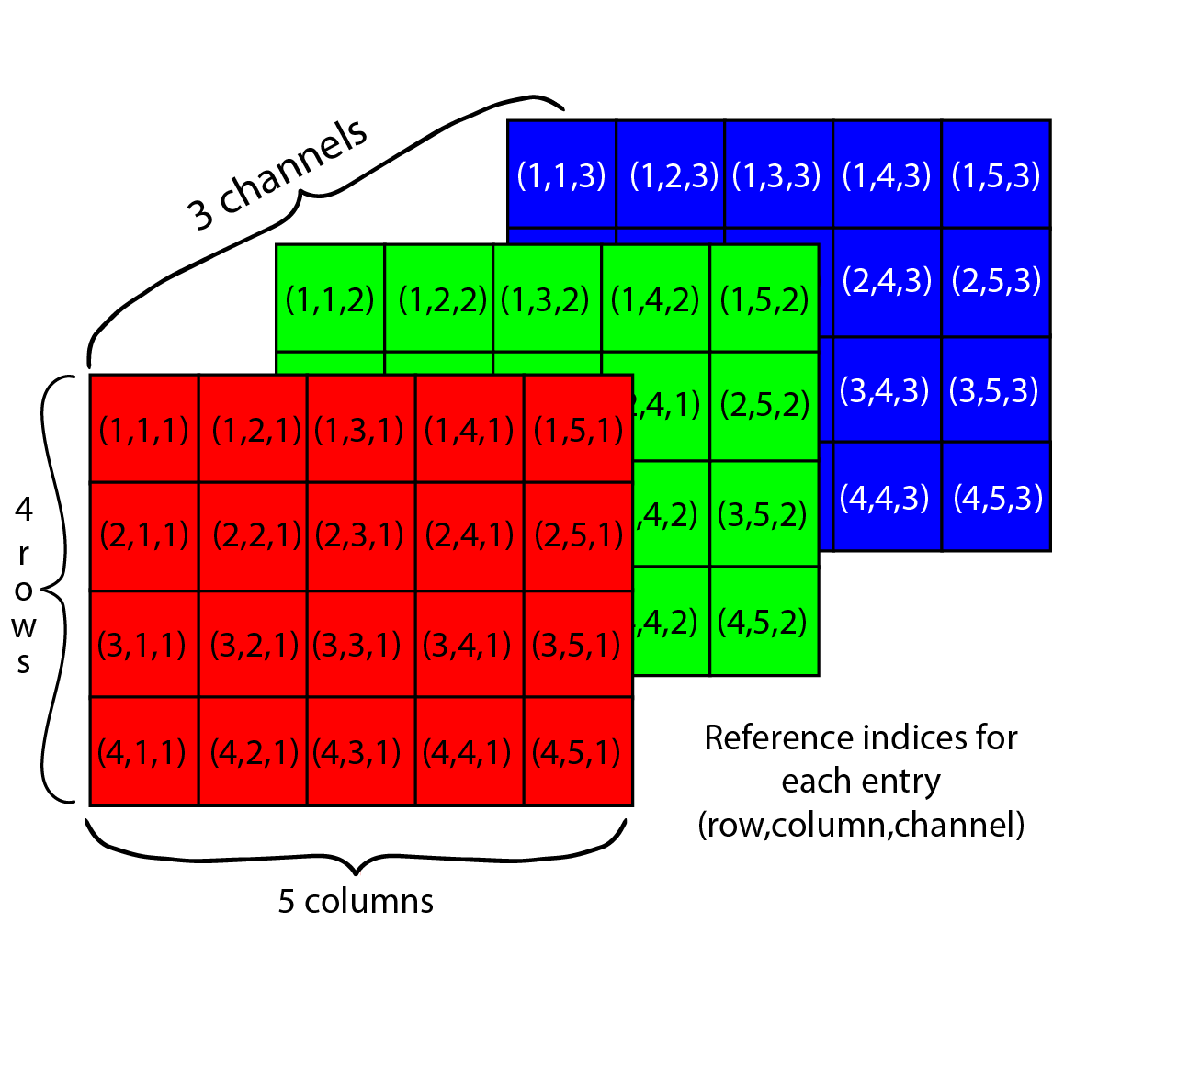

Nếu bạn xây dựng một mảng 3D với các kênh khác hoàn toàn`0`'S, bạn sẽ có thể tạo ra kết quả dự kiến ��cho`redchannel, Greenchannel,`Và`Bluechannel`Hình ảnh.

Ví dụ:

[RedChannel,GreenChannel,BlueChannel] = imsplit(PicTurkeys);
NoData = zeros(size(RedChannel));
OnlyRed = cat(3,RedChannel,NoData,NoData);
imshow(OnlyRed)

**Bài tập 5**

a. Sao chép và sửa đổi mã ví dụ để chỉ hiển thị kênh màu `OnlyGreen `Và kênh màu `OnlyBlue`

b. Kiểm tra xem kết quả của bạn có chính xác không bằng cách chạy

c. Đảo ngược kênh màu xanh lá cây bằng cách thay thế `Greenchannel `trong định nghĩa của`OnlyGreen `với `255-GreenChannel` Vì các giá trị cho mỗi phạm vi màu từ `0 `ĐẾN `255`. Sau đó hiển thị kết quả của bạn.

 **Phản ánh**

- Có những hạn chế nào về cấu trúc dữ liệu của bạn như một vectơ? Một ma trận? Bất kỳ loại mảng nào khác?

- Những lợi ích của việc cấu trúc dữ liệu của bạn như một vectơ, ma trận hoặc mảng khác là gì?

- Bạn có thể nghĩ ra bất kỳ lý do nào để tránh cấu trúc dữ liệu của bạn dưới dạng mảng không?

- Bạn muốn sử dụng các cấu trúc nào khác? Bạn có thể đưa ra bất kỳ ví dụ nào không?

## Tiếp tục

Bây giờ bạn đã đạt được một số quen thuộc với dữ liệu, đã đến lúc xem xét cách tận dụng sức mạnh của máy tính để đưa ra quyết định có kiểm soát về các hướng dẫn để chạy tiếp theo[Cành.mlx](matlab:open('./Branches.mlx'))

[Menu menu chính](matlab:open('MainMenu.mlx'))